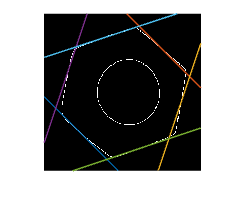

%%% 1.b

o= imread('HW2.jpg');
im= rgb2gray(o);
im = imbinarize(im);
im = edge(im, 'canny');


B = bwboundaries(im, 'holes');
B = B{1}; 


[gy, gx] = imgradientxy(im);

[row,col]=size(gx);
A= zeros(500,500);%%make a bigger A

for i=1:size(B,1)
        x=B(i,2);
        y=B(i,1);

        if gx(x,y)~=0 && gy(x,y)~=0
            v=(x*gx(x,y)+y*gy(x,y))./(gx(x,y)^2 + gy(x,y)^2);
            x0=round(v*gx(x,y));
            y0=round(v*gy(x,y));
            A(x0+100,y0+100)=A(x0+100,y0+100)+1;
        end
        

end

threshold = 50; % Adjust as needed
peak = houghpeaks(A, 8,Threshold=.01);

peak(7,:)=[];
peak(6,:)=[];
figure;
imshow(im);
hold on;
for i=1:6
    pointx0=peak(i,1) - 100;
    pointy0=peak(i,2) - 100;

    slope=-pointx0/pointy0;
    b=pointy0-pointx0.*slope;
    xx = 1:300;
    yy=xx.*slope + b;
    
    
    plot(xx,yy);
end

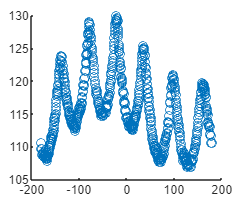


%%% 2.a

% https://github.com/CaiSean/Machine-Vision-ME6406/tree/master/Hough-Transform%20Example%20Code
clc
clear
clf

im= imread('HW2.jpg');
im= rgb2gray(im);
img_BW = imbinarize(im); 
img_BW = imcomplement(img_BW); 
B = bwboundaries(img_BW, 'holes');
B = B{1}; 
im = edge(img_BW);
[row,col]=size(im);
A=zeros(row,col);
s = regionprops(im,'Area', 'centroid');
centroids = cat(1, s.Centroid);

reference= centroids;
yc=reference(1,1);
xc=reference(1,2);
hold on
r=[];
X=[];
Y=[];
t=[];
x0 = B(:, 2); 
y0 = B(:, 1); 
x_X = x0 - xc;
y_Y = y0 - yc;
% for x =1:row
%     for y=1:col
for i = 1:length(B)
     X=[X i];
     Y=[Y i];
     rho(i, :)= (x_X(i).^2 + y_Y(i).^2).^0.5;
     theta(i,:)= atan2(y_Y(i),x_X(i))*180/pi; %%flip to get six points
          
          
end
xlabel('Theta- in radians');
ylabel('Distance- in pixels');
hold off

[peaks,locs]= findpeaks(rho,'MinPeakDistance',90);
xall=B(:,1);
yall=B(:,2);
scatter(theta,rho)

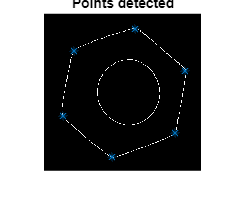


figure 
imshow(im)
hold on
plot( yall(locs),xall(locs),'*');
title('Points detected')
hold off

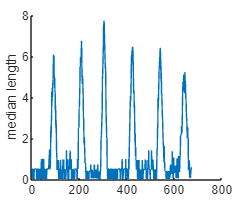

%%% 2.b

im= imread('HW2.jpg');
im= rgb2gray(im);

bwImg=im2bw(im,0.2);
bwImg=imcomplement(bwImg);

[B,L,N,A]= bwboundaries(bwImg);
xall=B{1}(:,1);
yall=B{1}(:,2);
X=[xall;xall]';
Y=[yall;yall]';
n=15;
D=[];
clf
hold on
for i=1:(size(X,2)/2)
    X0=X(i+n);
    X1=X(i);
    X2=X(i+2*n);
    Y0=Y(i+n);
    Y1=Y(i);
    Y2=Y(i+2*n);
     d= abs(((Y2-Y1)*X0 - (X2-X1)*Y0 +X2*Y1- Y2*X1)/((Y2-Y1)^2+(X2-X1)^2)^0.5);
    D=[D d];
end
clf

hold on
plot(1:size(X,2)/2,D);
ylabel('median length')
hold off

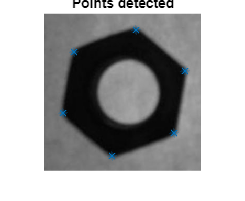


[peaks,locs]= findpeaks(D,'MinPeakDistance',60);
locs(1)=[];
locs= locs+n;
figure 
imshow(im)
hold on
plot( yall(locs),xall(locs),'*');
title('Points detected')
hold off

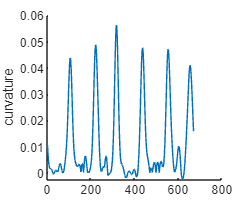

%%% 2.c
im= imread('HW2.jpg');
im= rgb2gray(im);
bwImg= im2bw(im,0.2);
bwImg= imcomplement(bwImg);
[B,L,N,A]= bwboundaries(bwImg,'noholes');
x=B{1}(:,2);
y=B{1}(:,1);
x=[x;x];
y=[y;y];
n=length(x);
s=linspace(-n/2,n/2,n);
sigma=8;
g0=1/sqrt(2*pi*sigma^2)*exp(-s.^2/(2*sigma^2));
g=[g0 g0]';
X=conv(x,g,'same');
X=X(1:round(end/2));
Y=conv(y,g,'same');
Y=Y(1:round(end/2));
Xd=diff(X);
Xdd=diff(Xd);
Yd=diff(Y);
Ydd=diff(Yd);
X_vec=[];
Y_vec=[];
for i=1:length(Xdd)
    X_vec=[X_vec X];
    Y_vec=[Y_vec Y];
    K(i)=abs(Xd(i)*Ydd(i))-(Xdd(i)*Yd(i));
end

clf

hold on
plot(1:length(K(1:end)),K(1:end));
ylabel('curvature');
hold off

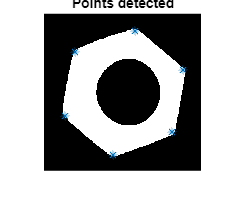

[peaks,locs]= findpeaks(K,'MinPeakDistance',70);

locs(1)=[];

figure 
imshow(bwImg)
hold on
plot( X_vec(locs),Y_vec(locs),'*');
title('Points detected')
hold off

%% 3.a

k=1.2;
theta=30;
theta_r= pi/6;
Xd=8;
Yd=5;

X=[0 6 2];
Y=[0 3 7];
Xc=(X(1)+X(2)+X(3))/3;
Yc=(Y(1)+Y(2)+Y(3))/3;

q1=k.*cos(theta_r);
q2=k.*sin(theta_r);
q3=Xc+Xd;
q4=Yc+Yd;
Q=[q1;q2;q3;q4];
R=[];

A=[X(1) -Y(1) 1 0;Y(1) X(1) 0 1;
   X(2) -Y(2) 1 0;Y(2) X(2) 0 1;
   X(3) -Y(3) 1 0;Y(3) X(3) 0 1];


R1 = A*Q;


cols=length(R1)/2;
R=reshape(R1,[2,cols]);
x1 = R(1,:);
y1 = R(2,:);
clf
plot([x1,R(1,1)], [y1,R(2,1)], 'b-'); 
grid on
hold on
% 'b-' specifies a blue line
plot([X,X(1)], [Y,Y(1)], 'r-');
hold off;
axis equal;



%% 3.b
Qt = (A'*A)^-1 *A'*R1;
kd_ = sqrt(Qt(1)^2 + Qt(2)^2)
theta_ = atan(Qt(2)/Qt(1))
xd_ = Qt(3)-Xc
yd_ = Qt(4)-Yc



Xte=[2 5 5 4 1];
Yte=[1 2 4 5 3];
Xta = [9.697 8.566 6.869];
Yta = [6.96 8.091 5.263];

Xte_c=sum(Xte)/5;
Yte_c=sum(Yte)/5;

Xta_c=sum(Xta)/3;
Yta_c=sum(Yta)/3;



% Load the template and target point sets
template_points = [2 1; 5 2; 5 4; 4 5; 1 3]; % Replace with the actual filename
target_points = [9.697 6.96; 8.566 8.091; 6.869 5.263];    % Replace with the actual filename


% Get the number of points
n = size(target_points, 1);


% Construct the design matrix A
A = zeros(2 * n, 4);
for i = 1:n
    A(2 * i - 1, :) = [template_points(i, 1), -template_points(i, 2), 1, 0];
    A(2 * i, :) = [template_points(i, 2), template_points(i, 1), 0, 1];
end

% Construct the vector b
b = reshape(target_points', [], 1);

% Calculate the least squares solution (transformation parameters)
x = pinv(A) * b;

% Extract transformation parameters
best_scale = sqrt(x(1)^2 + x(2)^2);
best_orientation = atan2(x(2), x(1)); % In radians
best_xd = x(3);
best_yd = x(4);

% Display the best match and transformation parameters
fprintf('Best Scale: %f\n', best_scale);
fprintf('Best Orientation (radians): %f\n', best_orientation);
fprintf('Best X Displacement: %f\n', best_xd);
fprintf('Best Y Displacement: %f\n', best_yd);

% Transform the entire template polygon using the best match parameters
scaled_template = best_scale * (template_points * [cos(best_orientation), -sin(best_orientation); sin(best_orientation), cos(best_orientation)]) + [best_xd, best_yd];

% Plot the target polygon and the transformed template polygon
figure;
plot(target_points(:, 1), target_points(:, 2), 'bo-', 'LineWidth', 2, 'MarkerSize', 10);
hold on;
plot(scaled_template(:, 1), scaled_template(:, 2), 'rx-', 'LineWidth', 2, 'MarkerSize', 10);
legend('Target Polygon', 'Transformed Template');
title('Polygon Matching Result');
axis equal;
hold off;




% Load the template and target point sets
template_points = [2 1; 5 2; 5 4; 4 5; 1 3]; % Replace with the actual filename
target_points = [9.697 6.96; 8.566 8.091; 6.869 5.263];    % Replace with the actual filename

% Get the number of points
n = size(target_points, 1);

% Initialize variables for the best match
best_scale = 0;
best_orientation = 0; % In radians
best_xd = 0;
best_yd = 0;
best_matching_error = inf; % Initialize with a large value
best_transformed_template = [];

% Create all possible permutations of vertex indices
vertex_indices = 1:n;
vertex_permutations = perms(vertex_indices);

% Iterate through each permutation
for i = 1:size(vertex_permutations, 1)
    % Extract the current permutation of vertex indices
    permutation = vertex_permutations(i, :);
    
    % Arrange the template points according to the current permutation
    arranged_template = template_points(permutation, :);
    
    % Calculate the centroids of the arranged template and target polygons
    template_centroid = mean(arranged_template);
    target_centroid = mean(target_points);
    
    % Translate both polygons to align their centroids
    translated_template = arranged_template - template_centroid;
    translated_target = target_points - target_centroid;
    
    % Calculate the transformation parameters using the pseudo-inverse method
    x = compute_transformation(translated_template, translated_target);
    
    % Extract transformation parameters
    scale = sqrt(x(1)^2 + x(2)^2);
    orientation = atan2(x(2), x(1));
    xd = x(3)-target_centroid(1);
    yd = x(4)-target_centroid(2);
    
    % Apply the transformation to the translated template
    transformed_template = scale * (translated_template * [cos(orientation), -sin(orientation); sin(orientation), cos(orientation)]) + [xd, yd];
    
    % Translate the transformed template back to its original position
    transformed_template = transformed_template + target_centroid;
    
    % Calculate the matching error (sum of squared differences)
    matching_error = sum(sum((target_points - transformed_template).^2));
    
    % Update the best match if the current one is better
    if matching_error < best_matching_error
        best_scale = scale;
        best_orientation = orientation;
        best_xd = xd;
        best_yd = yd;
        best_matching_error = matching_error;
        best_transformed_template = transformed_template;
    end
end

% Display the transformation parameters
fprintf('Best Scale: %f\n', best_scale);
fprintf('Best Orientation (radians): %f\n', best_orientation);
fprintf('Best X Displacement: %f\n', best_xd);
fprintf('Best Y Displacement: %f\n', best_yd);

% Plot the target polygon and the transformed template polygon
figure;
plot(target_points(:, 1), target_points(:, 2), 'bo-', 'LineWidth', 2, 'MarkerSize', 10);
hold on;
plot(best_transformed_template(:, 1), best_transformed_template(:, 2), 'rx-', 'LineWidth', 2, 'MarkerSize', 10);
legend('Target Polygon', 'Transformed Template');
title('Polygon Matching Result');
axis equal;
hold off;




% Load the template and target point sets
template_points = [2 1; 5 2; 5 4; 4 5; 1 3]; % Replace with the actual filename
target_points = [9.697 6.96; 8.566 8.091; 6.869 5.263];    % Replace with the actual filename

% Get the number of points
n_template = size(template_points, 1);
n_target = size(target_points, 1);

% Initialize variables for the best match
best_scale = 0;
best_orientation = 0; % In radians
best_xd = 0;
best_yd = 0;
best_matching_error = inf; % Initialize with a large value
best_transformed_template = [];

% Create all possible permutations of vertex indices for the template
template_vertex_indices = 1:n_template;
template_vertex_permutations = perms(template_vertex_indices);

% Iterate through each permutation of template vertices
for i = 1:size(template_vertex_permutations, 1)
    % Extract the current permutation of template vertex indices
    template_permutation = template_vertex_permutations(i, :);
    
    % Arrange the template points according to the current permutation
    arranged_template = template_points(template_permutation, :);
    
    % Calculate the centroid of the arranged template
    template_centroid = mean(arranged_template);
    
    % Translate both the arranged template and target polygons to align their centroids
    translated_template = arranged_template - template_centroid;
    translated_target = target_points - mean(target_points);
    
    % Calculate the transformation parameters using the pseudo-inverse method
    x = compute_transformation(translated_template, translated_target);
    
    % Extract transformation parameters
    scale = sqrt(x(1)^2 + x(2)^2);
    orientation = atan2(x(2), x(1));
    xd = x(3);
    yd = x(4);
    
    % Apply the transformation to the translated template
    transformed_template = scale * (translated_template * [cos(orientation), -sin(orientation); sin(orientation), cos(orientation)]) + [xd, yd];
    
    % Translate the transformed template back to its original position
    transformed_template = transformed_template + template_centroid;
    
    % Calculate the matching error (sum of squared differences)
    matching_error = sum(sum((target_points - transformed_template).^2));
    
    % Update the best match if the current one is better
    if matching_error < best_matching_error
        best_scale = scale;
        best_orientation = orientation;
        best_xd = xd;
        best_yd = yd;
        best_matching_error = matching_error;
        best_transformed_template = transformed_template;
    end
end

% Display the transformation parameters
fprintf('Best Scale: %f\n', best_scale);
fprintf('Best Orientation (radians): %f\n', best_orientation);
fprintf('Best X Displacement: %f\n', best_xd);
fprintf('Best Y Displacement: %f\n', best_yd);

% Plot the target polygon and the transformed template polygon
figure;
plot(target_points(:, 1), target_points(:, 2), 'bo-', 'LineWidth', 2, 'MarkerSize', 10);
hold on;
plot(best_transformed_template(:, 1), best_transformed_template(:, 2), 'rx-', 'LineWidth', 2, 'MarkerSize', 10);
legend('Target Polygon', 'Transformed Template');
title('Polygon Matching Result');
axis equal;
hold off;



% Function to compute transformation parameters using the pseudo-inverse method

function x = compute_transformation(template, target)
    % Construct the design matrix A
    n = size(target, 1);
    A = zeros(2 * n, 4);
    for i = 1:n
        A(2 * i - 1, :) = [template(i, 1), -template(i, 2), 1, 0];
        A(2 * i, :) = [template(i, 2), template(i, 1), 0, 1];
    end
    
    % Construct the vector b
    b = reshape(target', [], 1);
    
    % Calculate the least squares solution (transformation parameters)
    x = pinv(A) * b;
end





